# 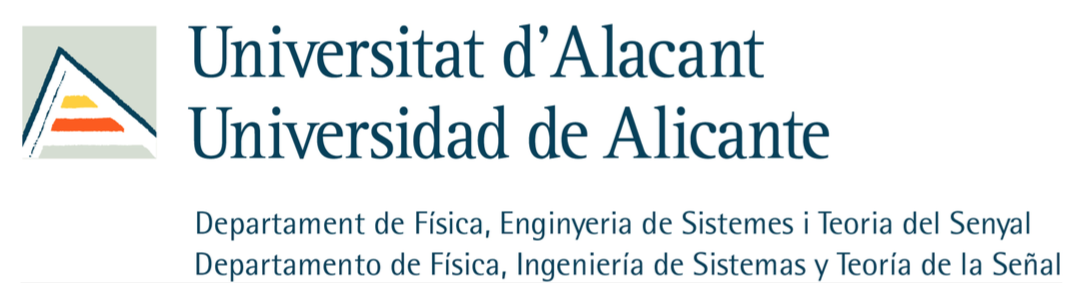

# Examen de Prácticas de Tratamiento digital de audio - 2015/16 - jmrplens

- **Código escrito sobre Matlab R2016b. Es posible que en versiones anteriores no funcionen algunas funciones para mostrar resultados por pantalla.**

- Ademas de este script se ha creado otro con menos lineas que realiza especificamente lo que se solicita en el enunciado, sin apuntes ni analisis en detalle y todo junto sin separar en secciones.

En un conflicto bélico nuestros espías han sido capaces de interceptar una de las comunicaciones del ejército enemigo. Sin embargo, la transmisión está cifrada por lo que de momento no se ha podido conocer ni el contenido de la grabación ni, por lo tanto, su alcance. Después de un análisis exhaustivo por parte de la división de inteligencia se cree que la transmisión emplea un scrambler para cifrar su mensaje, por lo que se ordena a ingeniería que intente descifrarlo programando para ello un descrambler. En el siguiente mensaje adjunto se incluyen tanto el fichero de audio cifrado como las órdenes a seguir para crear el descrambler.

## Problema 1. Toma de contacto (1 punto)

Cargar el fichero de audio en memoria y escucharlo. Extraer la información referente al formato de conversión A/D empleado y presentarla en pantalla: frecuencia de muestreo, profundidad de bits y cantidad de canales.

% Limpiar variables, ventanas y comandos
clear
close all
clc

% Obtencion de la señal
archivo = 'cifrado.wav';        % Para acceder al archivo
ubicacion = dir(archivo);       % Para utilizar funciones como .bytes
[cifrado,fs]=audioread(archivo);

% Obtencion de la informacion del audio
info_audio = audioinfo(archivo);
nbits = info_audio.BitsPerSample; % Matlab antiguo: '[S,fs,nbits]=wavread('...');'
nmuestras = length(cifrado);
canales = info_audio.NumChannels; % Tambien se puede obtener con 'size(cifrado,2)'
duracion = info_audio.Duration;
peso = ceil(ubicacion.bytes/1024); % Peso del archivo en KiloBytes

## Problema 1. Presentación de datos iniciales

Este apartado forma parte del **Problema 1**. Con estas lineas se mostrará una ventana con toda la información relevante del audio a decodificar.

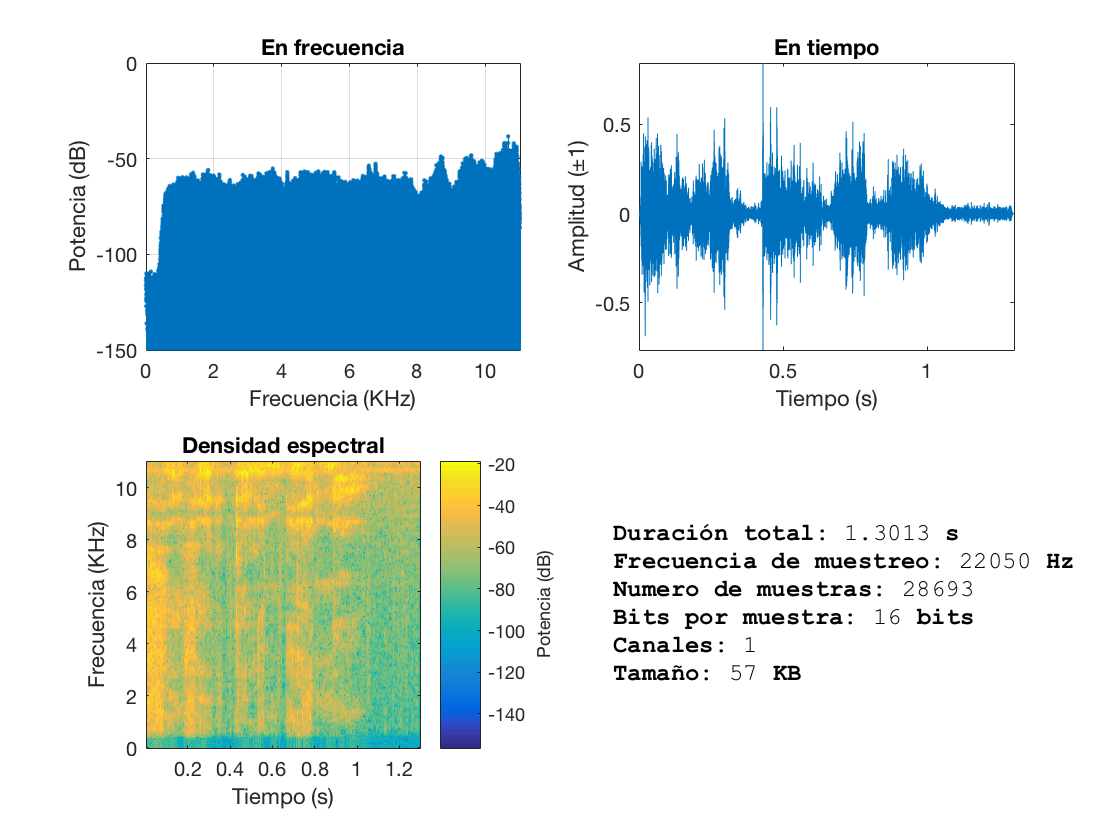

% Ventana nueva con titulo indicando los datos que muestra
figure('Name','Información del audio cifrado','NumberTitle','off');

% Espectro del audio cifrado
subplot(2,2,1)
periodogram(cifrado,rectwin(nmuestras),nmuestras,fs,'reassigned')
title('En frecuencia')
ylabel('Potencia (dB)');xlabel('Frecuencia (KHz)');
ylim([-inf,0])

% Nivel de amplitud respecto al tiempo del audio cifrado
subplot(2,2,2)
t = linspace(0, nmuestras/fs, nmuestras); % Tiempo eje X
plot(t,cifrado)
axis tight    % Ajusta los ejes de la grafica al valor maximo
title('En tiempo')
ylabel('Amplitud (±1)');
xlabel('Tiempo (s)')

% Densidad espectral del audio cifrado
subplot(2,2,3)
ventanaE = 256;              % Tamaño de la ventana
solapamientoE = [];          % Solapamiento vacio. 'Spectrogram' lo calcula para realizar un 50%
MargenFrecuencia = 0:fs/2;  % Vector de frecuencia a analizar. Mitad de la frecuencia de muestreo (Nyquist)
spectrogram(cifrado, ventanaE, solapamientoE, MargenFrecuencia, fs, 'yaxis','power');
title('Densidad espectral')
ylabel('Frecuencia (KHz)');xlabel('Tiempo (s)');
c = colorbar;c.Label.String = 'Potencia (dB)';

% Mostrar texto con información
subplot(2,2,4)
imtext=imshow(zeros(200, 300, 'uint8')); % Imagen negra para alojar el texto
set(imtext, 'AlphaData', 0);             % Convierte la imagen en trasparente
texto= {['',''],...
    ['\bfDuración total: \rm',num2str(duracion),' \bfs'],...
    ['\bfFrecuencia de muestreo: \rm',num2str(fs),' \bfHz'],...
    ['\bfNumero de muestras: \rm',num2str(nmuestras)],...
    ['\bfBits por muestra: \rm',num2str(nbits),' \bfbits'],...
    ['\bfCanales: \rm',num2str(canales)],...
    ['\bfTamaño: \rm',num2str(peso),' \bfKB'],...
    ['','']};
% Formato y posición del texto
text(-20,100,texto,'FontSize',12,'FontName','FixedWidth');


% Reproduccion del audio cifrado
sound(cifrado,fs,nbits)
pause(duracion) % Pausa la ejecucion de codigo hasta que se reproduce el audio completamente

## Problema 2. Procesado por bloques (4 puntos)

Preparar el esqueleto de código necesario para realizar un procesado por bloques genérico, en el cual se pueda controlar mediante variables los siguientes parámetros:

- Tamaño de bloque

- Perfil de ventana

- Solapamiento entre bloques

El código debe ser capaz de funcionar de forma autónoma independientemente del número de muestras que contenga el sonido original.

tamBloque = 512;                % Tamaño de bloque
ventana = hanning( tamBloque ); % Perfil de ventana
valSolapamiento = 50;           % Solapamiento en %
solapamiento = tamBloque * ( valSolapamiento / 100 );

% Numero de ventanas necesarias a procesar segun el numero de muestras que
% tenga la señal. Se resta 1 para no rebasar la duracion de la misma.
num_ventanas_generico = floor(length(cifrado)/solapamiento)-1;

% Inicialización del vector/matriz que almacenará la señal procesada
generico = zeros(size(cifrado));

for i=1:num_ventanas_generico
    
    iniBloque = (i-1)*solapamiento+1; % Valor para calcular el inicio de la ventana 'i'
    finBloque = (i+1)*solapamiento;   % Valor para calcular el final de la ventana 'i'
    
    % Obtencion de las muestras para crear el bloque
    Bloque = cifrado(iniBloque:finBloque);
    
    % Bloque procesado con la ventana recibida
    Bloque_enventanado = Bloque.*ventana;
    
    %
    % Aqui el codigo con el que se quiera procesar por bloques la señal
    %
    
    % Bloque_enventanado se cambiará por la salida del procesado a incluir
    Bloque_procesado = Bloque_enventanado; 
    
    % Unión de los bloques para crear la señal
    generico(iniBloque:finBloque) = generico(iniBloque:finBloque)+Bloque_procesado;
    
end

## Problema 3. Descrambler (3 puntos)

Un [scrambler](https://en.wikipedia.org/wiki/Scrambler) es un sistema de codificación que consiste en invertir el espectro (intercambia las altas frecuencias por las bajas frecuencias). Por tanto, un descrambler debe recolocar cada componente frecuencial en su posición original. Añadir las líneas de código necesarias para reconstruir el espectro original del sonido. Este código deberá incluirse en el interior del bloque de procesado por bloques, por lo que deberá de trabajar únicamente con bloques de sonido, no con el fichero de sonido completo. Emplear para ello los siguientes parámetros:

- Tamaño de bloque: 512 muestras

- Perfil de Ventana: hanning

- Solapamiento: 50%

tamBloque = 512;                % Tamaño de bloque
ventana = hanning( tamBloque ); % Perfil de ventana
valSolapamiento = 50;           % Solapamiento en %
solapamiento = tamBloque * ( valSolapamiento / 100 );

% Numero de ventanas necesarias a procesar segun el numero de muestras que
% tenga la señal. Se resta 1 para no rebasar la duracion de la misma.
numero_ventanas = floor(length(cifrado)/solapamiento)-1;

% Inicialización del vector/matriz que almacenará la señal procesada
descifrado = zeros(size(cifrado));

% Recorre la señal tantas veces como numero de ventanas sean necesarias
for i=1:numero_ventanas
    
    iniBloque = (i-1)*solapamiento+1; % Valor para calcular el inicio de la ventana 'i'
    finBloque = (i+1)*solapamiento;   % Valor para calcular el final de la ventana 'i'
    
    % Obtencion de las muestras para crear el bloque
    Bloque = cifrado(iniBloque:finBloque);
    
    % Bloque procesado con la ventana recibida
    Bloque_enventanado = Bloque.*ventana;
    
    % Lineas de codigo para realizar el descrambler
    
    % Bloque a frecuencia para recolocar las componentes frecuenciales
    Bloque_freq = fft(Bloque_enventanado); 
    
    % Se copia la segunda mitad de la componente frecuencial del bloque
    % cifrado a la primera mitad del bloque descifrado
    Bloque_freq_descifrado(1:tamBloque/2)=Bloque_freq(tamBloque/2+1:tamBloque);
    
    % Se copia la primera mitad de la componente frecuencial del bloque
    % cifrado a la segunda mitad del bloque descifrado
    Bloque_freq_descifrado(tamBloque/2+1:tamBloque)=Bloque_freq(1:tamBloque/2);
    
    % Bloque a tiempo
    Bloque_descifrado=ifft(Bloque_freq_descifrado)';
    
    % Unión de los bloques para crear la señal
    descifrado(iniBloque:finBloque) = descifrado(iniBloque:finBloque)+Bloque_descifrado;
    
end

## Problema 4. Re-ensamblado (1,5 puntos)

Añadir las líneas de código necesarias para ensamblar cada uno de los bloques procesados y formar el sonido final descifrado. Almacenar la solución en un fichero wav.

`El código necesario para ensamblar los bloques es la ultima linea dentro del 'for' del problema anterior. La linea es la siguiente:`

descifrado(iniBloque:finBloque) = descifrado(iniBloque:finBloque)+Bloque_descifrado;

% Normalización del audio descifrado
descifrado = descifrado/max(abs(descifrado));

% Reproducción del audio descifrado
sound(descifrado,fs,nbits)
pause(duracion) % Pausa la ejecucion de codigo hasta que se reproduce el audio completamente

% Almacenamiento del audio descifrado
audiowrite('descifrado.wav',descifrado,fs);

## Problema 4. Presentación de datos finales

Este apartado no es necesario pero se implementa para comparar con la información obtenida del archivo original.

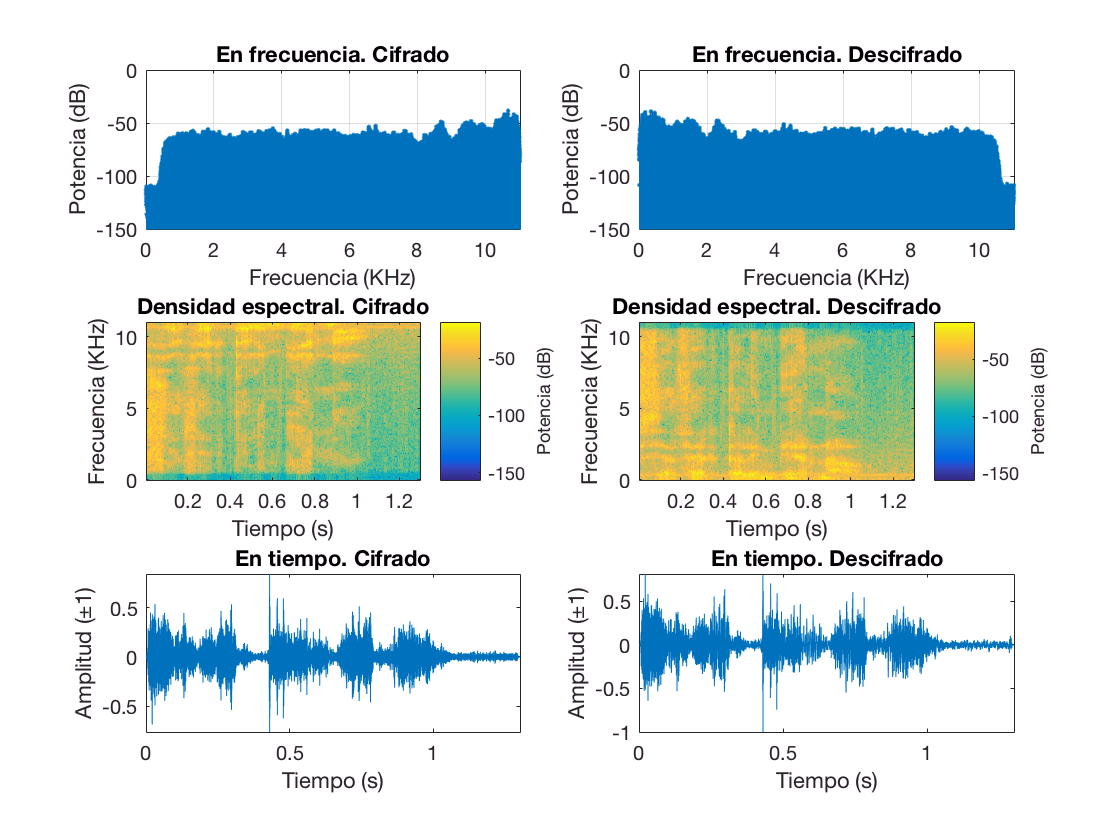

% Ventana nueva con titulo indicando los datos que muestra
figure('Name','Comparación del audio cifrado y descifrado','NumberTitle','off');

% Espectro del audio cifrado
subplot(3,2,1)
periodogram(cifrado,rectwin(nmuestras),nmuestras,fs,'reassigned')
title('En frecuencia. Cifrado')
ylabel('Potencia (dB)');xlabel('Frecuencia (KHz)');
ylim([-inf,0])

% Espectro del audio descifrado
subplot(3,2,2)
periodogram(descifrado,rectwin(nmuestras),nmuestras,fs,'reassigned')
title('En frecuencia. Descifrado')
ylabel('Potencia (dB)');xlabel('Frecuencia (KHz)');
ylim([-inf,0])

% Parametros para realizar el analisis de densidad espectral
ventanaE = 256;              % Tamaño de la ventana
solapamientoE = [];          % Solapamiento vacio. 'Spectrogram' lo calcula para realizar un 50%
MargenFrecuencia = 0:fs/2;  % Vector de frecuencia a analizar. Mitad de la frecuencia de muestreo (Nyquist)

% Densidad espectral del audio cifrado
subplot(3,2,3)
spectrogram(cifrado, ventanaE, solapamientoE, MargenFrecuencia, fs, 'yaxis','power');
title('Densidad espectral. Cifrado')
ylabel('Frecuencia (KHz)');xlabel('Tiempo (s)');
c = colorbar;c.Label.String = 'Potencia (dB)';

% Densidad espectral del audio descifrado
subplot(3,2,4)
spectrogram(descifrado, ventanaE, solapamientoE, MargenFrecuencia, fs, 'yaxis','power');
title('Densidad espectral. Descifrado')
ylabel('Frecuencia (KHz)');xlabel('Tiempo (s)');
c = colorbar;c.Label.String = 'Potencia (dB)';

% Nivel de amplitud respecto al tiempo del audio cifrado
subplot(3,2,5)
t = linspace(0, nmuestras/fs, nmuestras); % Tiempo eje X
plot(t,cifrado)
axis tight    % Ajusta los ejes de la grafica al valor maximo
title('En tiempo. Cifrado')
ylabel('Amplitud (±1)');
xlabel('Tiempo (s)')

% Nivel de amplitud respecto al tiempo del audio descifrado
subplot(3,2,6)
t = linspace(0, nmuestras/fs, nmuestras); % Tiempo eje X
plot(t,descifrado)
axis tight    % Ajusta los ejes de la grafica al valor maximo
title('En tiempo. Descifrado')
ylabel('Amplitud (±1)');
xlabel('Tiempo (s)')

## Problema 5. Solución (0,5 puntos)

¿Cuál es el mensaje cifrado original? Escribe la solución como un comentario en el propio código.

%
% El mensaje es: "Se acerca el invierno"
%